clc;
close all;
clear all;

heart_data=readtable('Data.csv');    % reading the data
shape_data=size(heart_data);     % finding the data size
check_null=isempty(heart_data);     % checking for null values

CLASS DISTRIBUTION

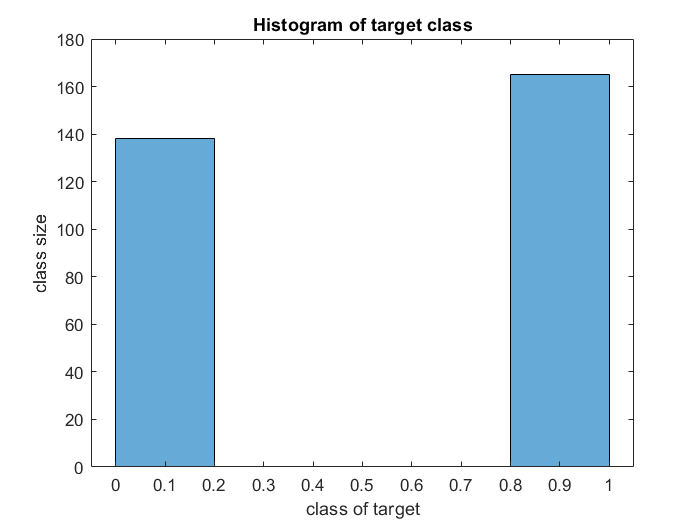

p= table2array(heart_data);   % converting into array
x=p(:,1:13);              % columns containing features are assigned to x
y=p(:,14);                     % targets column is assigned to y
nbins=5;
histogram(y,nbins)             % displaying the histogram
xlabel('class of target')
ylabel('class size')
title('Histogram of target class')

FEATURE SELECTION BASED ON CORRELATION COEFFICIENT

[R,P] = corrcoef(p); % calculating the correlation coefficient
figure
R

R =     1.0000   -0.0984   -0.0687    0.2794    0.2137    0.1213   -0.1162   -0.3985    0.0968    0.2100   -0.1688    0.2763    0.0680   -0.2254
   -0.0984    1.0000   -0.0494   -0.0568   -0.1979    0.0450   -0.0582   -0.0440    0.1417    0.0961   -0.0307    0.1183    0.2100   -0.2809
   -0.0687   -0.0494    1.0000    0.0476   -0.0769    0.0944    0.0444    0.2958   -0.3943   -0.1492    0.1197   -0.1811   -0.1617    0.4338
    0.2794   -0.0568    0.0476    1.0000    0.1232    0.1775   -0.1141   -0.0467    0.0676    0.1932   -0.1215    0.1014    0.0622   -0.1449
    0.2137   -0.1979   -0.0769    0.1232    1.0000    0.0133   -0.1510   -0.0099    0.0670    0.0540   -0.0040    0.0705    0.0988   -0.0852
    0.1213    0.0450    0.0944    0.1775    0.0133    1.0000   -0.0842   -0.0086    0.0257    0.0057   -0.0599    0.1380   -0.0320   -0.0280
   -0.1162   -0.0582    0.0444   -0.1141   -0.1510   -0.0842    1.0000    0.0441   -0.0707   -0.0588    0.0930   -0.0720   -0.0120    0.1372
   -0.398

s=size(p,1); %  total number of rows

% r value of 3th feature(chest pain type) with target= 0.4338
% r value of 9th feature(exercise induced angina) with target= -0.4368
% r value of 3th and 9th feature = -0.3943

x1=p(:,3); % 3th feature assigned to x1
x2=p(:,9);   % 9th feature assigned to x2
y=p(:,14);      % target assigned to y

NORMALISING THE SELECTED FEATURES

% Z SCORE NORMALIZATION = (xi-mean(x))/standard deviation(x) 
stand_x1=(x1-mean(x1))/std(x1);
stand_x2=(x2-mean(x2))/std(x2);

TRAIN -TEST SPLIT

% 90 percent of data is taken as train set & 10 percent is for test set 
% Train data points = 273
% Test data points = 30
train_size=round(s*0.9);

% to split train and test data points randomly
rng(100) % control random number generator
t=randsample(s,s);     % random number of size 303 of range 1 to 303 has been generated
train_ind=t(1:train_size,1);     %taking the first 273 randomly generated numbers and saving it as train indices
test_ind=t(train_size+1:s,1);           %taking the remaining 30 randomly generated numbers and saving it as test indices

% pointing the train indices to the normalized features x1 & x2 and also to the target
train_x1=stand_x1(train_ind);    
train_x2=stand_x2(train_ind);
train_y=y(train_ind);

% pointing the test indices to the normalized features x1 & x2 and also to the target
test_x1=stand_x1(test_ind);
test_x2=stand_x2(test_ind);
test_y=y(test_ind);

m=train_y; % to retain the target labels of the train
accuracy=[]; % creating an empty array to append the accuracy for each k value

KNN CLASSIFICATION ALGORITHM IMPLEMENTATION - CHEBYSHEV DISTANCE MEASURE

   63.3333

    60

    60

    60

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

    80

   73.3333

    80

   73.3333

    80

    80

    80

   73.3333

    80

    80

    80

    80

    80

    80

   76.6667

    80

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

   76.6667

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    70

    

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   73.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333

   53.3333



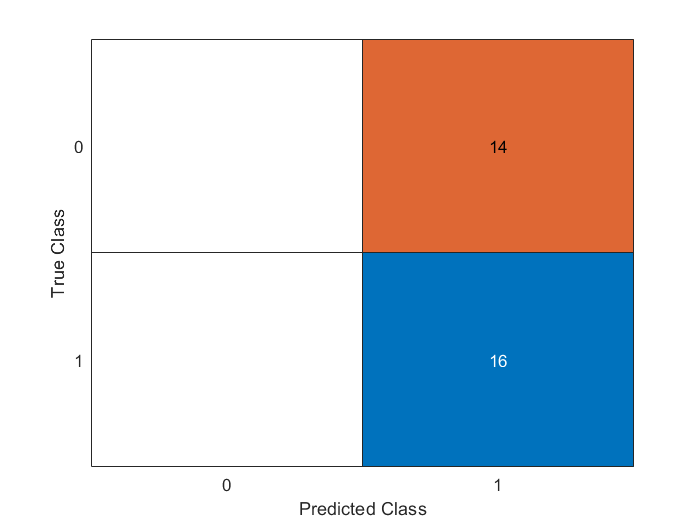

   53.3333



for k=1:size(train_y,1) % iterating for a range of k values (no.of neighbors)
    output=[];              % creating an empty array to append the predicted target of test points
    
    % calculating Chebyshev distance for each test points with all train points
    % CHEBYSHEV DISTANCE FORMULA = MAX(sum(absolute(train_data-test_data)))
    for i=1:length(test_y)
        distance=[];
        for j=1:length(train_y)
            Chebyshev_distance=max(abs(train_x1(j)-test_x1(i)),abs(train_x2(j)-test_x2(i)));
            distance=[distance Chebyshev_distance];       % appending the distance value for each test data with all train data
        end
        
    dis_temp=0;   % creating a temporary distance variable for sorting
    class_temp=0;    % creating a temporary target variable for sorting
    
    % sorting the distance and target in ascending order
    
    for i=1:length(distance)
        for j=1:(length(distance)-i)   
            if (distance(j)> distance(j+1)) % checking for the greater value
                dis_temp=distance(j);   % assigning the greater  value to a temporary variable
                distance(j)=distance(j+1);   % assigning the smallest value to the place of greater value
                distance(j+1)=dis_temp;  % assigning the greater value which is stored in the temporary variable to the position of the smallest value
                
                class_temp=m(j);
                m(j)= m(j+1);
                m(j+1)=class_temp;
            end
        end
    end
    
    % based on the k value taking the k number of nearest neighbors
   target=[];  % creating an empty array to append the  k number of target classes
   for i=1:k
       target(i)=m(i);
   end
   
   output=[output mode(target)]; % to return the most frequently occuring value
   m=train_y; % retaining back the train target for next test point
   end
   
   % creating a confusion matrix to know the no. of misclassified targets and correctly classified targets
   confusion=confusionchart(test_y,output);
   
   % Accuracy calculation using confusion matrix
   % Accuracy= (TP+TN)/(TP+TN+FP+FN)
   accuracy_compute=(sum(diag(confusion.NormalizedValues))/length(test_y))*100;
   disp(accuracy_compute)
   accuracy =[accuracy accuracy_compute];
end

% Error_rate=(FP+FN)/(TP+TN+FP+FN) OR 1-Accuracy
error_rate=1-(accuracy/100);

PLOTTING ACCURACY Vs k values

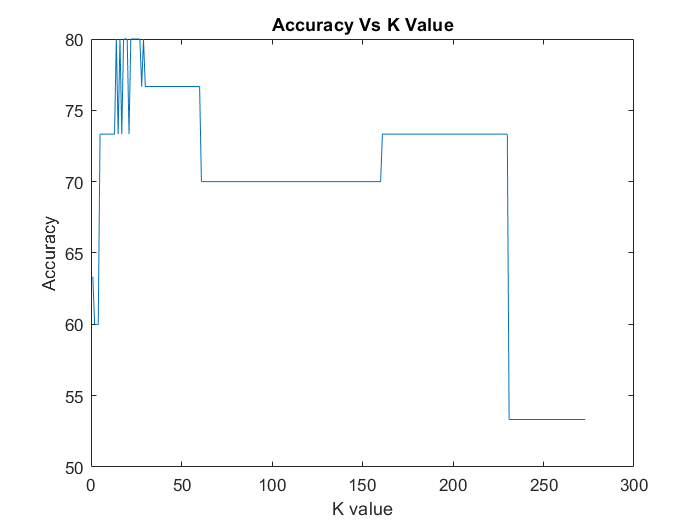

plot(accuracy)
xlabel('K value')
ylabel('Accuracy')
title('Accuracy Vs K Value')

figure

PLOTTING ERROR_RATE Vs k value

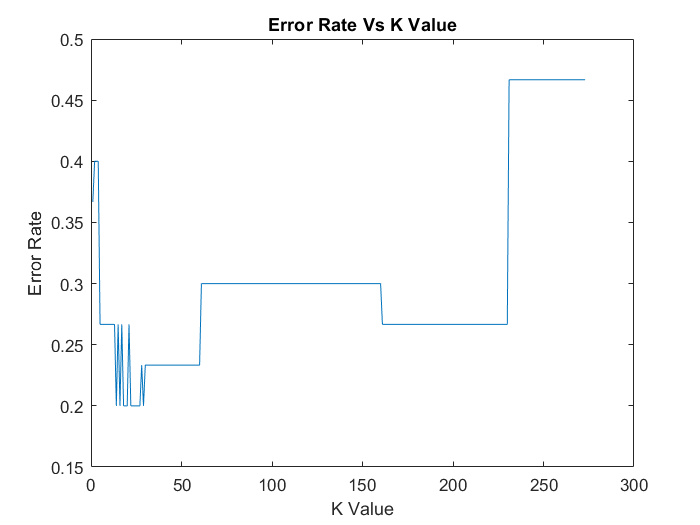

plot(error_rate)
xlabel('K Value')
ylabel('Error Rate')
title('Error Rate Vs K Value')